clear all;
close all;

tau = 0.05

tau = 0.0500

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



alpha = (s*tau + 1)^2

alpha =
 
  0.0025 s^2 + 0.1 s + 1
 
Continuous-time transfer function.




beta = (0.5*s + 1)^3

beta =
 
  0.125 s^3 + 0.75 s^2 + 1.5 s + 1
 
Continuous-time transfer function.




GHsym = [s^2/alpha, -1/alpha, -1/alpha, 0;
         1/alpha, (alpha - 1/alpha)/s^2, -1/(s^2 * alpha), 1/s^2;
         (1-1/alpha)/beta, -(alpha-1/alpha)/(beta * s^2), 1/(beta*s^2*alpha), -1/(beta*s^2);
         s^2/(beta*alpha), (1-1/alpha)/beta, -1/(beta*alpha), 0]

GHsym =
 
  From input 1 to output...
                s^2
   1:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
                 1
   2:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
                              0.0025 s^2 + 0.1 s
   3:  -----------------------------------------------------------------
       0.0003125 s^5 + 0.01438 s^4 + 0.2038 s^3 + 0.9025 s^2 + 1.6 s + 1
 
                                      s^2
   4:  -----------------------------------------------------------------
       0.0003125 s^5 + 0.01438 s^4 + 0.2038 s^3 + 0.9025 s^2 + 1.6 s + 1
 
  From input 2 to output...
                 -1
   1:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
       6.25e-06 s^4 + 0.0005 s^3 + 0.015 s^2 + 0.2 s
   2:  ---------------------------------------------
                0.0025 s^4 + 0.1 s^3 + s^2
 
                  -6.25e-06 s^4 - 0.0005 s^3 - 0.015 s^2 - 0.2 s
   3:  ---------------------------------------------------------------------
       0.



Gss_q1 = ss(GHsym, 'minimal')

Gss_q1 =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10
   x1     -1.724   -0.7257    -0.747    0.2172    0.4639     2.056    -3.072     6.068     6.218     3.181
   x2      5.355    -2.829   -0.7498    0.2905   -0.7323   -0.8566   -0.2803    0.4823     0.919    0.5518
   x3    0.09853    0.2385     -2.38    0.1399     5.679     6.494    -1.414    0.1492   -0.7512    -0.428
   x4    -0.2761    0.2006    0.7872   -0.1393    -1.546    -1.749    0.6382   -0.1675  -0.05538   0.03149
   x5      1.241   -0.9019    -0.386     0.265    -1.417    -2.407   -0.7065     1.345     1.229    0.1085
   x6     -2.156     1.566    0.6703    -0.219  -0.08788    -2.486    0.8503    -1.744    -1.501    -1.529
   x7      7.092    -5.152    -2.205    0.7205    0.2882     1.365    -5.794     8.031     5.573     -1.32
   x8     -15.84     11.51     4.926    -1.609   -0.6436    -3.049     5.846    -13.92    -14.78    -6.099
   x9     -16.36   

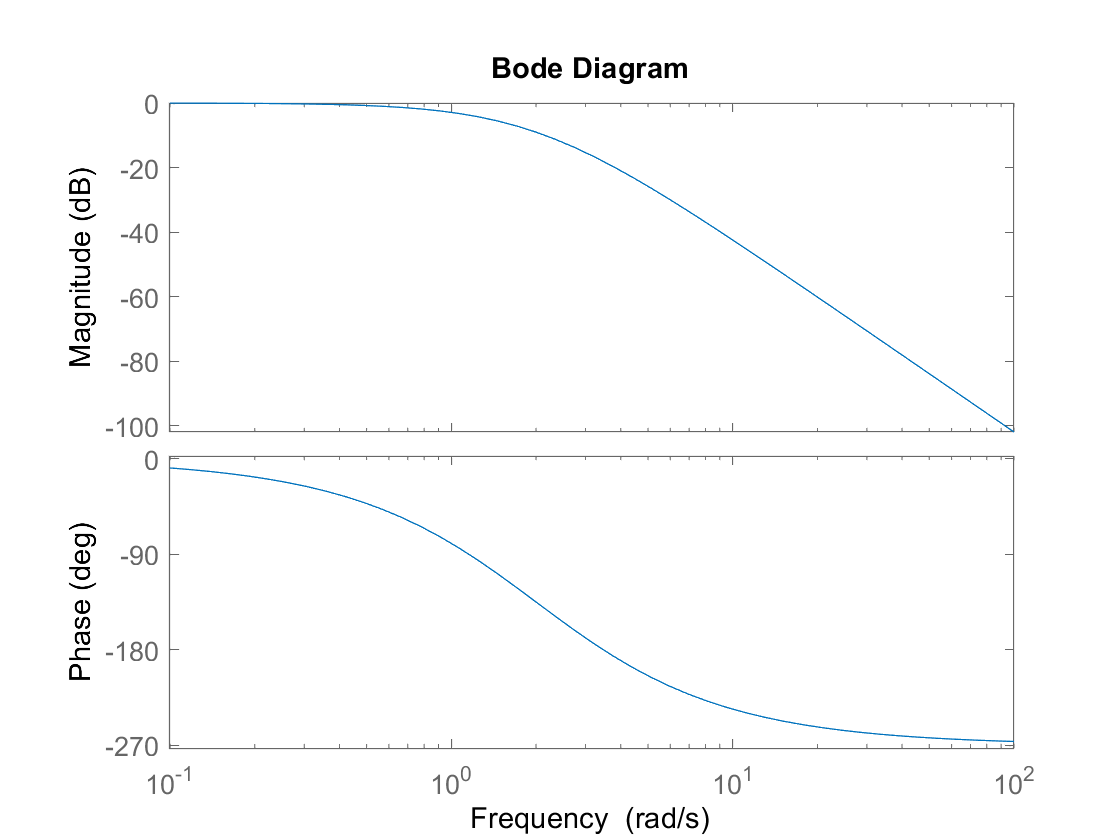


bode(1/beta)

% realised that matlab uses [z; y] when the q1 has asked for [y; z]

% form subsystem from r to e
ny = 2;
nz = 2;
new_order = [ny+1 : ny+nz, 1 : ny];

Gss = ss(Gss_q1.A, Gss_q1.B, Gss_q1.C(new_order, :), Gss_q1.D(new_order, :));


## []


A =  Gss.A;
B = Gss.B;
Bw = Gss.B(:, 1:2);
Bu = Gss.B(:, 3:4);
C = Gss.C(1:2, :);
D = Gss.D;
D_w = Gss.D(1:2, 1:2);
D_u = Gss.D(1:2, 3:4); % goes w then u


n = size(A, 1);
m = size(Bu, 2);

% literally copied exactly from the fucking lecture notes and it doesnt
% work
% UPDATE: IT WORKS

cvx_begin sdp
    variable Y(n,n) symmetric
    variable Z(m,n)
    variable gama

    LMI1 = Y >= 0

 
Constraint accepted
 


    LMI2 = gama <= 0.1

 
Constraint accepted
 


    
    LMI3 = [ (Y*A' + A*Y + Z'*Bu' + Bu*Z),   (Y*C' + Z'*D_u'),          Bw;
            (C*Y + D_u*Z),  -gama*eye(2),      D_w';
            Bw',            D_w,                -gama*eye(2) ] <= 0;
cvx_end

 
Calling SDPT3 4.0: 161 variables, 76 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 76
 dim. of sdp    var  = 24,   num. of sdp  blk  =  2
 dim. of linear var  =  1
 number of nearly dependent constraints = 1
 To remove these constraints, re-run sqlp.m with OPTIONS.rmdepconstr = 1.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.1e+03|3.9e+00|3.0e+04| 4.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.311|0.534|7.5e+02|1.8e+00|2.4e+04|-5.613452e+02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.6

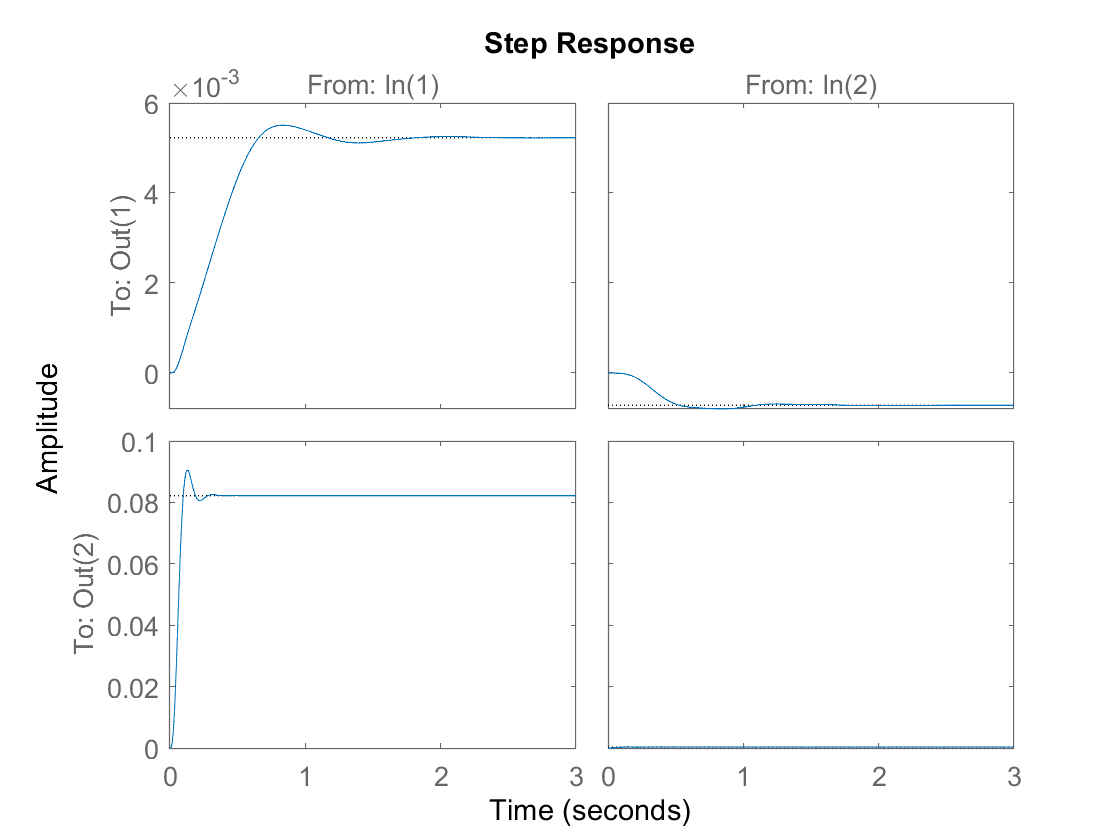

K = Z / Y;

A_cl = A + Bu * K;
B_cl = Bw;
C_cl = C + D_u * K;
D_cl = D_w;

Gcl = ss(A_cl, B_cl, C_cl, D_cl);

step(Gcl)

## Passivity LMI

% system definition

tau = 0.05

tau = 0.0500

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



alpha = (s*tau + 1)^2

alpha =
 
  0.0025 s^2 + 0.1 s + 1
 
Continuous-time transfer function.




beta = (1 - 1/alpha)

beta =
 
    0.0025 s^2 + 0.1 s
  ----------------------
  0.0025 s^2 + 0.1 s + 1
 
Continuous-time transfer function.




GHpsym = [1/s, 1/(s*alpha), 1/s, 0;
          1/(s*alpha), 1/s, 0, 1/s;
          beta/(s^2), -beta/(s^2), 1/(s^2), -1/(s^2);
          beta/s, -beta/s, 1/s, -1/s]

GHpsym =
 
  From input 1 to output...
       1
   1:  -
       s
 
                  1
   2:  ------------------------
       0.0025 s^3 + 0.1 s^2 + s
 
           0.0025 s^2 + 0.1 s
   3:  --------------------------
       0.0025 s^4 + 0.1 s^3 + s^2
 
          0.0025 s^2 + 0.1 s
   4:  ------------------------
       0.0025 s^3 + 0.1 s^2 + s
 
  From input 2 to output...
                  1
   1:  ------------------------
       0.0025 s^3 + 0.1 s^2 + s
 
       1
   2:  -
       s
 
          -0.0025 s^2 - 0.1 s
   3:  --------------------------
       0.0025 s^4 + 0.1 s^3 + s^2
 
         -0.0025 s^2 - 0.1 s
   4:  ------------------------
       0.0025 s^3 + 0.1 s^2 + s
 
  From input 3 to output...
       1
   1:  -
       s
 
   2:  0
 
        1
   3:  ---
       s^2
 
       1
   4:  -
       s
 
  From input 4 to output...
   1:  0
 
       1
   2:  -
       s
 
       -1
   3:  ---
       s^2
 
       -1
   4:  --
       s
 
Continuous-time transfer function.




Gss_q2 = ss(GHpsym, 'minimal')

Gss_q2 =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1       -31.3     -0.9265       3.481      -5.063      -30.72      -8.603       3.003
   x2      -12.77      -2.799    -0.06832       13.55      -6.945       1.233     -0.3366
   x3      -4.701       -2.11     -0.9947       10.14      -0.767        1.66     -0.5946
   x4   -0.005161   -0.002154  -0.0008383      -33.05      -13.62    -0.02876     -0.0447
   x5  -0.0007032  -0.0002935  -0.0001142       12.52      -6.943     0.01251     0.02049
   x6       11.61       4.844       1.885      -24.74       1.938      -4.407       1.487
   x7      -4.004      -1.671     -0.6504       8.537     -0.6691       1.521     -0.5129
 
  B = 
               u1          u2          u3          u4
   x1      -1.402       7.518     0.09296    -0.09973
   x2       1.613       2.221     -0.4984      0.5316
   x3       1.427      0.5045     -0.8684       0.926
   x4      -7.333     -0.1863    0.00

ny = 2;
nz = 2;
new_order = [ny+1 : ny+nz, 1 : ny];

Gpss = ss(Gss_q2.A, Gss_q2.B, Gss_q2.C(new_order, :), Gss_q2.D(new_order, :));

% g prefix means its the LMI for the gain

A =  Gpss.A;
B = Gpss.B;
Bw = Gpss.B(:, 1:2);
Bu = Gpss.B(:, 3:4);
Cz = Gpss.C(1:2, :);
D = Gpss.D;
Dzw = Gpss.D(1:2, 1:2);
Dzu = Gpss.D(1:2, 3:4); % goes w then u

% p prefix means its the LMI for passivity
C = Gpss.C

C =     0.2087   -1.0917    0.8423    0.0120    0.0327   -0.2589    0.0893
    0.0813   -0.3182   -0.5828   -0.1259   -0.4273   -0.4669    0.0628
   -0.0576   -0.0406   -0.1236    0.0930   -0.2479   -0.7352   -1.3362
   -0.1389    0.2776    0.4592    0.2189    0.1793   -0.2683   -1.3990


Cy = Gpss.C(3:4, :);
Dyw = Gpss.D(3:4, 1:2);
Dyu = Gpss.D(3:4, 3:4); % goes w then u

## separate LMIs


n = size(A, 1)

n = 7

m = size(Bw, 2)

m = 2


cvx_begin sdp
    variable Y(n,n) symmetric
    variable Z(m,n)
    variable epsilon
    variable gama
    
    %minimise(gama)
    minimise(epsilon) % otherwise makes very high

    LMI1 = Y >= 0

 
Constraint accepted
 


    LMI2 = gama <= 0.1

 
Constraint accepted
 


    
    % gain LMI
    %
    LMI3 = [ (Y*A' + A*Y + Z'*Bu' + Bu*Z),   (Y*Cz' + Z'*Dzu'),          Bw;
            (Cz*Y + Dzu*Z),  -gama*eye(2),      Dzw';
            Bw',            Dzw,                -gama*eye(2) ] <= 0;
    
    LMI4 = epsilon >= 0

 
Constraint accepted
 


    LMI5 = [ Y*A' + A*Y + Bu*Z + Z'*Bu', Bw - Y*Cy' - Z'*Dyu';
             Bw' - Cy*Y-Dyu*Z,   -2*epsilon*eye(2) - (Dyw + Dyw')] <= 0

 
Constraint accepted
 


         
cvx_end

 
Calling SDPT3 4.0: 141 variables, 44 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 44
 dim. of sdp    var  = 27,   num. of sdp  blk  =  3
 dim. of linear var  =  2
 number of nearly dependent constraints = 1
 To remove these constraints, re-run sqlp.m with OPTIONS.rmdepconstr = 1.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+03|1.9e+01|3.7e+04| 8.800000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.430|0.377|1.2e+03|1.2e+01|2.8e+04|-6.081697e-02 -4.569051e+01| 0:0:00| chol  1  1 
 2|0.9

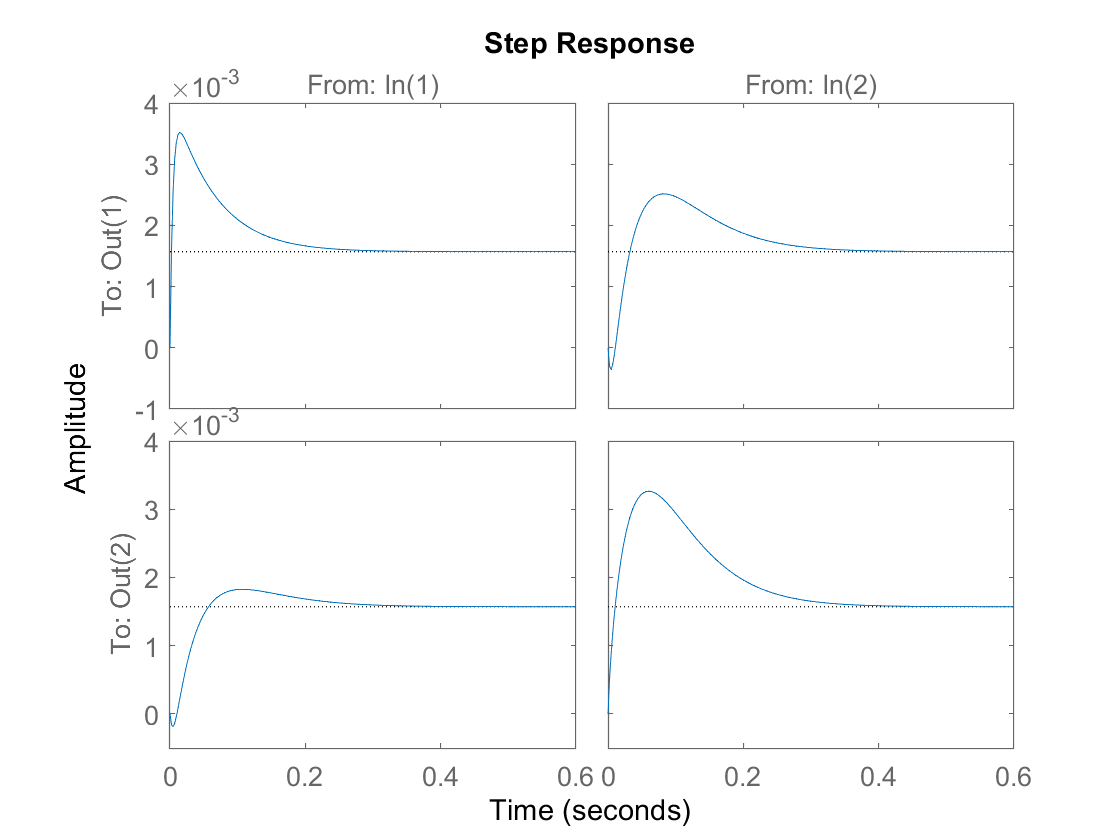


K = Z / Y;

A_pcl = A + Bu * K;
B_pcl = Bw;
C_pcl = Cy + Dyu * K;
D_pcl = Dyw;

Gpcl = ss(A_pcl, B_pcl, C_pcl, D_pcl);

step(Gpcl)

isPassive(Gpcl)

ans = logical
   1


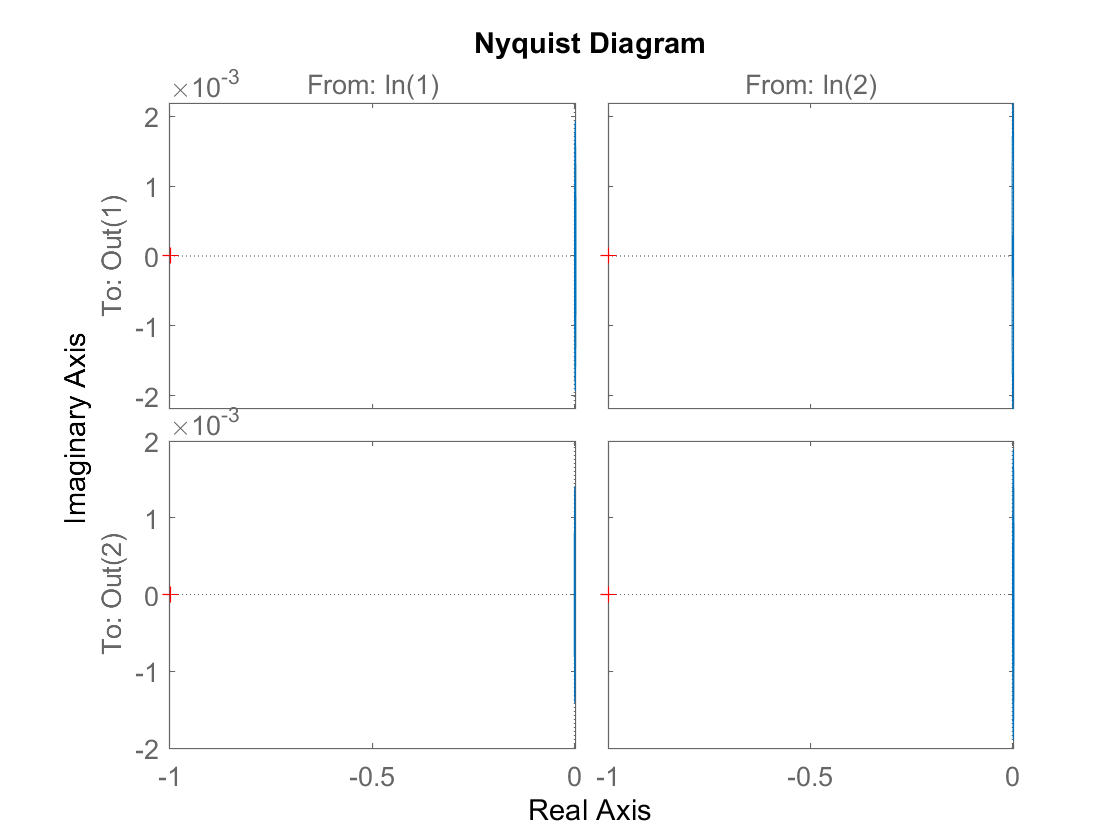


nyquist(Gpcl)